clear;

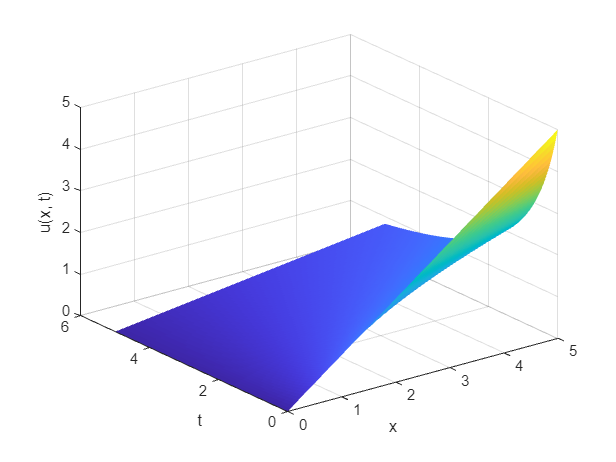

% initial condition g(x) = x
% soln exists for t >= 0

u = @(x, t) x ./ (t+1);

N = 100;
xx = linspace(0, 5, N);
tt = linspace(0, 5, N);
[X, T] = meshgrid(xx, tt);
U = u(X, T);

figure();
view(3);
xlabel('x'); ylabel('t'); zlabel('u(x, t)');
xticks(0:1:5);
grid on;

hold on;
% plot3(xx, tt, u(xx, tt), 'k-');
surf(X, T, U, 'EdgeColor', 'none');
hold off;

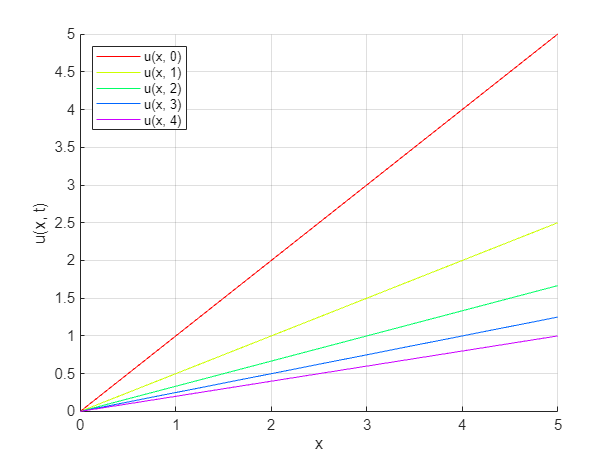

figure();
view(2);
legend('Location', 'northwest');
xlabel('x'); ylabel('u(x, t)');
xticks(0:1:5);
grid on;

C = hsv(5);

hold on;
formatSpec = "u(x, %d)";
for i = 0:1:4
    name = sprintf(formatSpec, i);
    plot(xx, u(xx, i*ones(1, N)), 'color', C(i+1, :),...
        'DisplayName', name);
end
hold off;

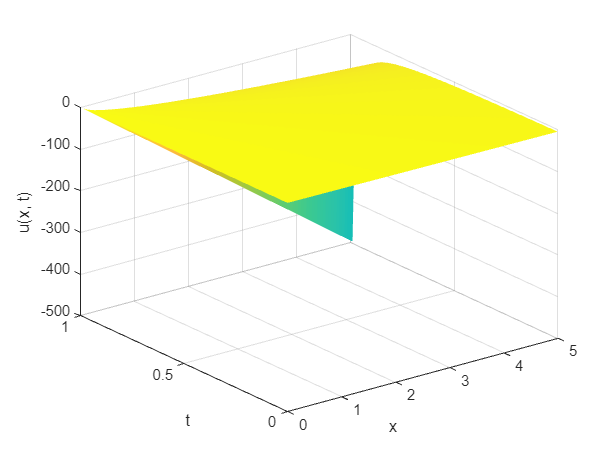

% initial condition g(x) = -x
% soln only exists for 0 <= t < 1

u = @(x, t) -x ./ (1-t);

N = 100;
xx = linspace(0, 5, N);
tt = linspace(0, 1, N);
[X, T] = meshgrid(xx, tt);
U = u(X, T);

figure();
view(3);
xlabel('x'); ylabel('t'); zlabel('u(x, t)');
xticks(0:1:5);
grid on;

hold on;
% plot3(xx, tt, u(xx, tt), 'k-');
surf(X, T, U, 'EdgeColor', 'none');
hold off;

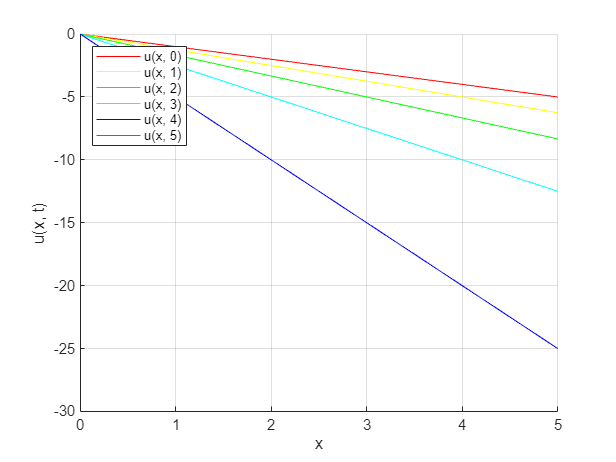

figure();
view(2);
legend('Location', 'northwest');
xlabel('x'); ylabel('u(x, t)');
xticks(0:1:5);
grid on;

C = hsv(6);

hold on;
formatSpec = "u(x, %d)";
for i = 0:1:5
    name = sprintf(formatSpec, i);
    plot(xx, u(xx, i/5*ones(1, N)), 'color', C(i+1, :),...
        'DisplayName', name);
end
hold off;